# **HomeWork n.2 2021/22**

### **Camilla De Martino**

#### **0124002258**

Usiamo il *format long *per tutti i risultati:

%visualizzo 15 cifre dopo la virgola
format long 

### **N.1  ****INTERPOLAZIONE:**

Definire un dominio $[a,b]$ ed una funzione composta $f(x)$ in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc.). Per stabilire un intervallo nel quale $f$sia definita e non prensenti punti di discontinuità, utilizzare eventualmente la function MATLAB *ezplot *per osservarne il grafico. 

Definire quindi un insieme di $m$ punti $P=\{(x_i,y_i)\}_{i=1}^m$ con $11 \leq m \leq 21, m \in \mathbb{N}$. Le ascisse di $P$ sono linearmente distribuite in $[a,b]$, le ordinate sono i

corrispondenti valori assunti dalla valutazione di $f(x)$.

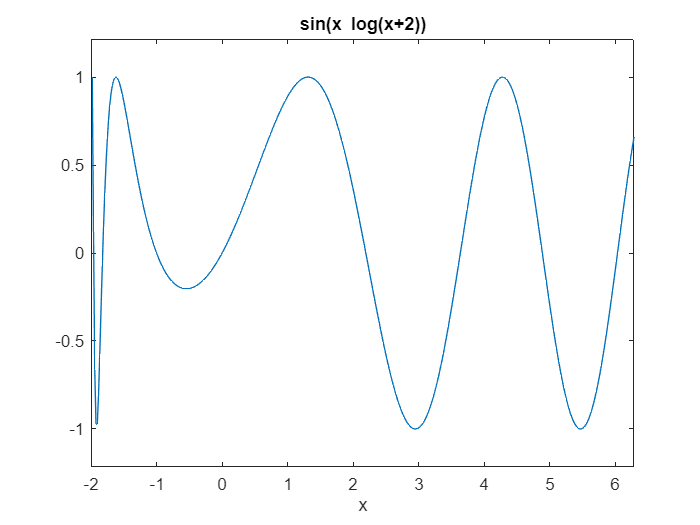

%definizione della funzione composta f(x), data la combinazione delle principali funzioni elementari

f = @(x) sin(x.* log(x+2));

figure(1)
ezplot(f);

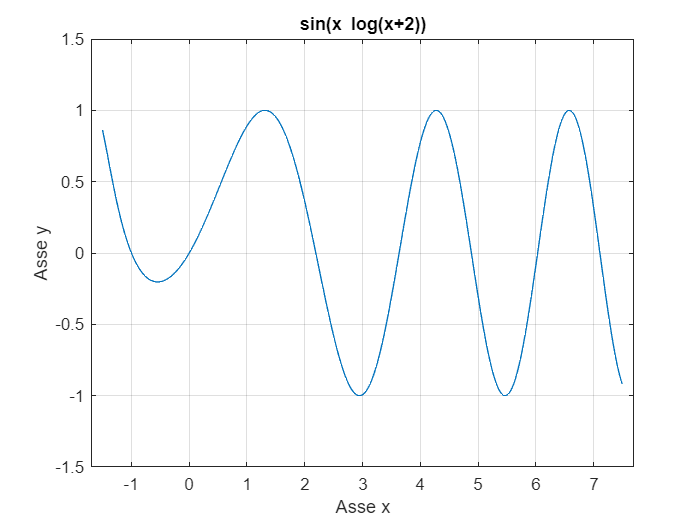

%utilizzo inizialmente ezplot senza un intervallo iniziale per poter verificare che non prensenti punti di discontinuità
%scelgo poi l'intervallo da considerare
estremo_sx = -1.5;
estremo_dx = 7.5;

%scelgo un m numero di nodi
m = 15;

%definisco il passo di incremento
x = linspace(estremo_sx, estremo_dx, m)';

%calcolo i valori
y = f(x);

ezplot(f, [estremo_sx, estremo_dx])
hold on
grid on
axis([estremo_sx - 0.2, estremo_dx + 0.2, -1.5, 1.5])

xlabel('Asse x')
ylabel('Asse y')

**PUNTO 1.1;**

**Definire un insieme **$\mathcal{F}$**di funzioni modello polinomiali. Scegliere un'opportuna base così da determinare il polinomio **$p$  $\in$ $\mathcal{F}$** che interpola **$f$** nei nodi **$x_i$**. Costruire e risolvere il relativo sistema lineare **$Ba=y$** (non usare il comando backslash di MATLAB).  Calcolare inoltre l'indice di condizionamento della matrice **$B$**.**

Assumiamo che la nostra base sia x^(j - 1) per j = 2 : m. La scelta di imporre j=2 e non uguale ad 1 è dovuta al fatto che la matrice di Vandermonde prevede che gli elementi della prima colonna siano tutti 1 (ossia x^0 ) ed eseguiremmo operazioni superflue.

Al fine di poter migliorare la velocità di esecuzione inizializiamo la matrice B tramite la funzione *once*.

%funzione modello b
b = @(x,j) x.^(j-1);
B = ones(m,m);

for j = 2 : m
    B(:, j) = b(x, j);
end

%risolvo il sistema lineare senza usare il comando backslash
a = SGauss(B, y);

ind_condB = cond(B)

ind_condB =      2.025181569274731e+14


L'indice di condizionamento è un valore elevato dunque ammissibile.

**PUNTO 1.2:**

**Valutare il polinomio **$p$** su una griglia di **$N$** punti di valutazione distribuiti casualmente in **$[a,b]$**. Fissare **$N\,\,( 201 \leq N \leq 399)$**. Calcolare l'errore di interpolazione della funzione interpolante scelta al punto precedente.**

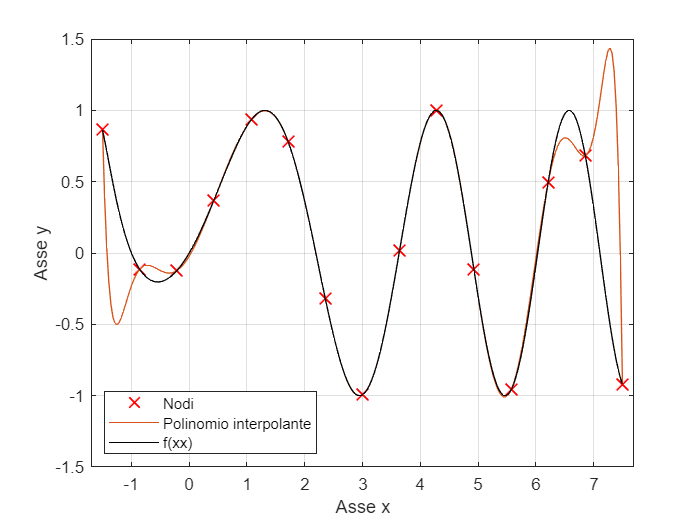

%Scelgo N = 250 e imposto la griglia.
N = 250;
xx = linspace(estremo_sx, estremo_dx, N)';

%genero la matrice di VANDERMONDE i cui input sono le valutazioni delle funzioni b(x) sui punti di valutazione xx

BB = ones(N, m);
for j = 2 : m
    BB(:, j) = b(xx, j);
end

%calcolo il polinomio interpolante
yy = BB * a; 

figure(3)
plot(x, y, 'x', 'MarkerSize', 10, 'Color', 'r','LineWidth', 1)
hold on
grid on

axis([estremo_sx - 0.2, estremo_dx + 0.2, -1.5, 1.5])
plot(xx, yy)
plot(xx, f(xx), 'Color', 'k')

xlabel('Asse x')
ylabel('Asse y')
legend('Nodi', 'Polinomio interpolante', 'f(xx)', 'Location', 'southwest')

errore = abs(yy - f(xx))

errore =    0.000000000000000
   0.408785304034631
   0.678961013597076
   0.840994261558020
   0.920093089435929
   0.936986086431047
   0.908593580709652
   0.848605701939382
   0.767980648019164
   0.675374479668844


Notiamo che le oscillazioni aumentano alle estremità dell'intervallo considerarto, dunque in quei punti l'errore amenta progressivamente.

**PUNTO 1.3:**

**Interpolare i punti **$P$** mediante una spline **$s$** di terzo grado di tipo *****not-a-knot*****.  Valutare l'interpolante ottenuto sulla una griglia di **$N$** punti di valutazione.**

`La funzione ppval` ci consente di valutare un polinomio a tratti su un insieme di ascisse, che costuiscono la nostra griglia di valutazione.

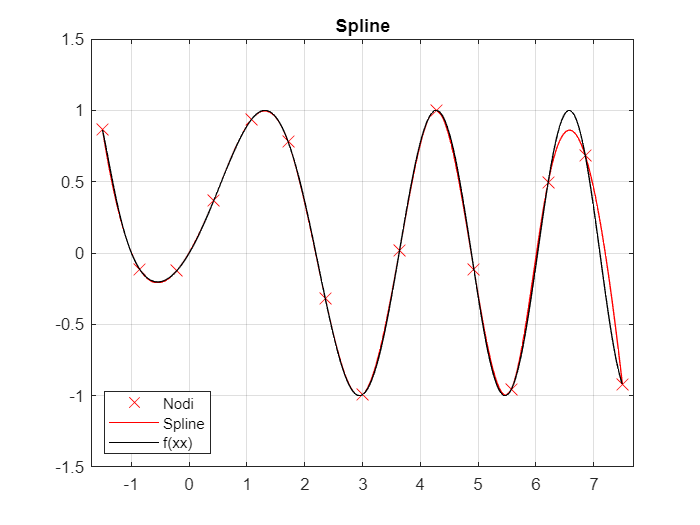

pp = spline(x, y);
yy_spline = ppval(pp, xx);

figure(4)
plot(x, y, 'x', 'MarkerSize', 10, 'color', 'r')

hold on
grid on
axis([estremo_sx - 0.2, estremo_dx + 0.2, -1.5, 1.5])

plot(xx, yy_spline, 'r')
plot(xx, f(xx), 'k')
title('Spline')
legend('Nodi', 'Spline', 'f(xx)', 'Location', 'southwest')

Notiamo che la spline ci consente di avere una precisione più accurata.

**PUNTO 1.4:**

**Fissare un valore **$n\,\,( 10 \leq n \leq 19)$** e definire un nuovo insieme di punti **$Q = \{(x_j, y_j)\}_{j=1}^n$** le cui ascisse sono i nodi di Chebyshev in **$[a,b]$** e le cui ordinate sono i valori corrispondenti assunti da **$f(x)$**. Costruire il polinomio interpolante i punti **$Q$** e valutarlo sulla griglia di valutazione generata al punto 1.2.**

fai la definizione dei nodi di chebyshev e come li metti in ordine crescente

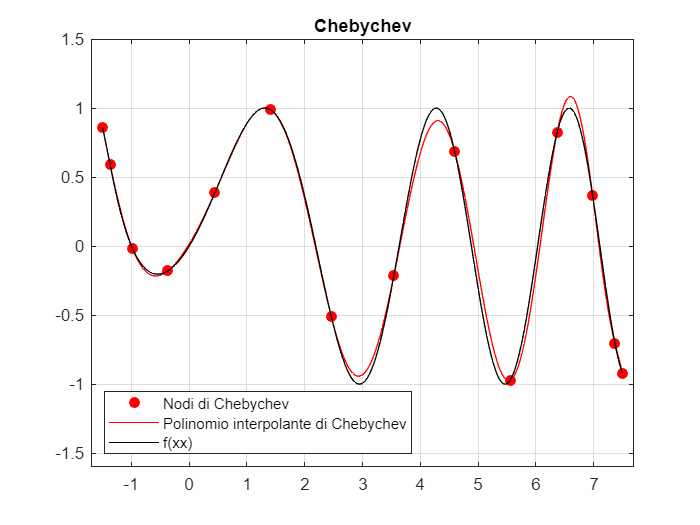

%scelgo la mia n uguale a 14
n = 14;

%poiché è utile ordinare i nodi in senso crescente, sfruttiamo le proprietà
%del coseno
x_cheb = -cos([0 : n - 1] * pi/(n - 1));

%nodi di chebychev per un intervallo [a,b]
x_chebt = ((estremo_sx + estremo_dx) / 2 + (estremo_dx - estremo_sx) / 2 * x_cheb)';    % Nodi di Chebychev traslati
y_cheb = f(x_chebt);             

% Ripetiamo lo stesso procedimento di prima ma per i nodi di Chebychev
B_cheb = ones(n, n);
for j = 1 : n
    B_cheb(:, j) = b(x_chebt, j);
end
a_cheb = SGauss(B_cheb, y_cheb);

BB_cheb = ones(N, n);
for j = 1 : n
    BB_cheb(:, j) = b(xx, j);
end

%risolvo il sistema lineare per i nodi di Chebychev
yy_cheb = BB_cheb * a_cheb;

figure(5)
plot(x_chebt, y_cheb, 'o', 'color', 'r', 'MarkerFaceColor','r')
hold on
grid on
axis([estremo_sx - 0.2, estremo_dx + 0.2, -1.6, 1.5])

plot(xx, yy_cheb, 'r')
plot(xx, f(xx), 'k')
title('Chebychev')
legend('Nodi di Chebychev', 'Polinomio interpolante di Chebychev', 'f(xx)', 'Location', 'southwest')

**PUNTO 1.5:**

**Infine, mostrare graficamente l'andamento dell'errore di interpolazione. Confrontare numericamente l'errore con quello ottenuto al punto 1.2**

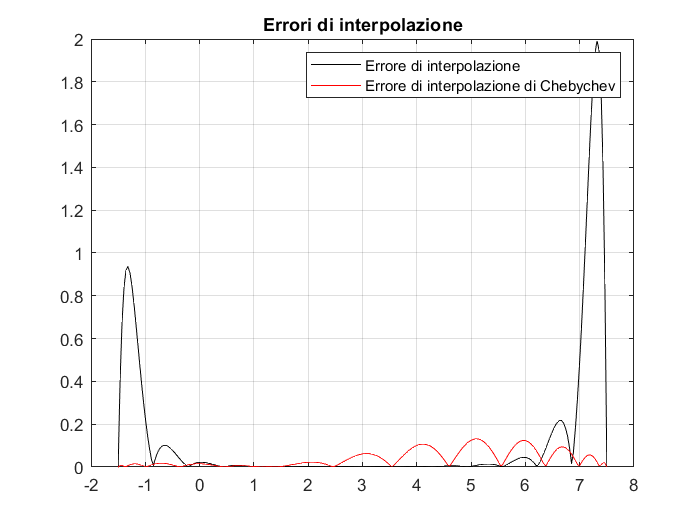

errore2 = abs(f(xx) - yy_cheb);
figure(6)

plot(xx, errore, 'k')
hold on
grid on
plot(xx, errore2, 'r' )
title('Errori di interpolazione')
legend('Errore di interpolazione', 'Errore di interpolazione di Chebychev')

% è un comando di tipo logical dove 1 = vero ed utilizzo per paragonare gli
% errori di entrambe le interpolazioni
errore2 < errore 

ans = 250×1 logical array
   0
   1
   1
   1
   1
   1
   1
   1
   1
   1


Si noti che, sia dal risultato grafico che dal risultato di tipo logical riportato dall'errore, l'errore di interpolazione ottenuto con i nodi Chebychev è diminuito di molto agli estremi rispetto all'errore di interpolazione calcolato in precedenza, con sostanziale attenuazione delle oscillazioni agli estremi dell'intervallo. Al centro invece l'errore aumentato leggermente, ma l'accuratezza è comunque molto buona e la ricostruzione è quindi migliorata.

**PUNTO 1.6:**

**Considerare il poligono di **$N$**vertici costituito dai valori della curva parametrica interpolata al punto (1.2) e, tramite il comando **`fill, `**visualizzare in una figura tale poligono colorato con un colore generato da una terna RGB.**

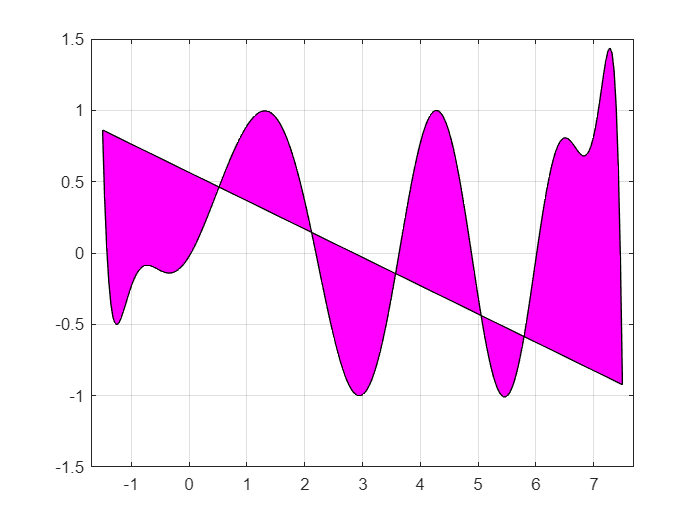

rgb = [1, 0, 1];
figure(7)
plot(xx, yy)
hold on
grid on
axis([estremo_sx - 0.2, estremo_dx + 0.2, -1.5, 1.5])
fill(xx, yy, rgb)

### **N.2 ****INTERPOLAZIONE DI CURVE PARAMETRICHE:**

  Si considerino le seguenti curve parametriche:

         1. $x = 4\sin\Big(\frac{1}{4}t\Big)\quad\quad y = 1 - 2\cos^2\Big(\frac{1}{4}t\Big)\quad\quad -52\pi \leq t \leq 34\pi$

         2. $x = 2e^t\quad\quad y = \cos(1+e^{3t})\quad\quad  0 \leq t \leq \frac{3}{4}$

         3. $x = t\cos(t)\quad\quad y = t\sin(t)\quad\quad -2\pi \leq t \leq 2\pi$

         4. $x = \cos t
 + \frac{1}{4}\cos(8t)\quad\quad y = \sin t + \frac{1}{4}\sin(8t)\quad\quad 0\leq t \leq 2\pi$

Scegliere una di tali curve e campionarla in $n$ punti $P=\{(x_i,y_i)\}_{i=1}^n$, corrispondenti a $n$ punti $t_i$ equispaziati nell'intervallo $[a,b]$ in cui varia il parametro $t$ (fissare $20<n<30$).

%scelgo la seconda curva in cui il parametro t è  definito nell'intervallo
%[0, 3/4] con 22 nodi equispaziati

x_curva = @(t) 2 .* exp(t);
y_curva = @(t) cos(1 + (exp(3.*t)));

t = linspace(0, 3/4, 22);

**PUNTO 2.1:**

**Costruire due spline parametriche **$p_x$** e **$p_y$** che interpolino rispettivamente i punti **$(t_i,x_i)$** e i punti **$(t_i, y_i)$**  (**$i = 1,\ldots, n$**);**

px = x_curva(t);
py = y_curva(t);

**PUNTO 2.2:**

**Valutare le spline parametriche su una griglia fitta opportuna e mostrare il grafico della curva parametrica interpolata.**

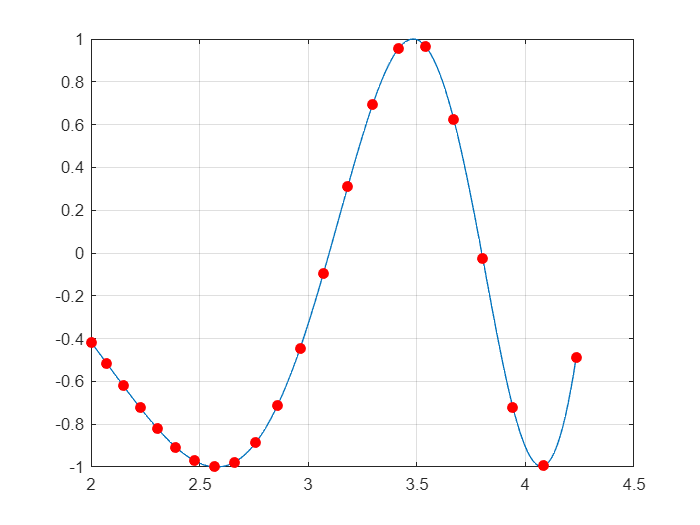

%stabiliamo la nostra griglia fitta

griglia_curva = linspace(0, 3/4, 250);
x_spline = spline(t, px, griglia_curva);
y_spline = spline(t, py, griglia_curva);

figure(8)
plot(x_spline, y_spline)
hold on
grid on
plot(px, py, 'o', 'color', 'r', 'MarkerFaceColor','r')
hold off

Si può notare che dall'interpolazione ottenuta tramite la spline, si ottiene un grafico passante per i punti x,y, nodi di una funzione parametrica.

**PUNTO 2.3:**

**Ripetere i punti (2.1) e (2.2) su un insieme di **$m=40$** punti **$S = \{(x_j,y_j)\}_{j=1}^m$** le cui ascisse ed ordinate sono valori ottenuti dall'utilizzo del comando **`ginput`** usato su una immagine a propria scelta oppurtunamente caricata (usare **`imread). `**Le coordinate devono essere estese aggiungendo in coda un punto fittizio uguale al primo punto, in modo tale che **`x`** e **`y`** siano i vettori delle coordinate dei vertici di un poligono (chiuso). **

Utilizziamo la funzione ginput per selezionare manualmente 40 punti, che delineano il contorno dell'immagine caricata, e salvarli nel file DatiHW2. Commento in seguito le funzioni per non dover inserire ad ogni run i 40 punti.

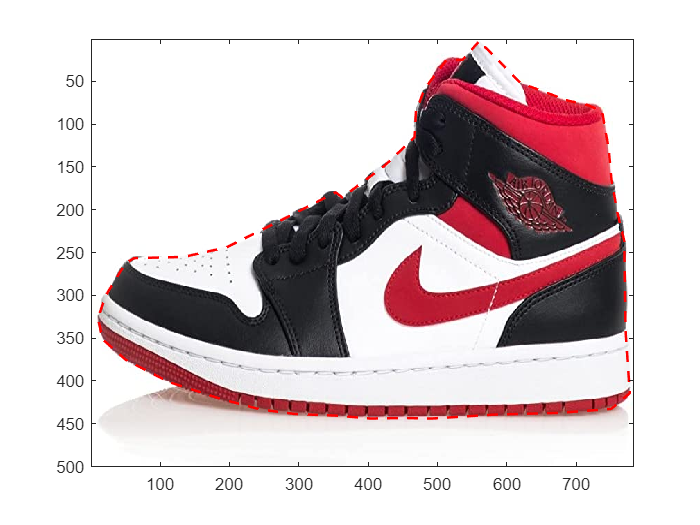

figure(9)
scarpa = imread("image\scarpe.jpg");
image(scarpa);
hold on
%[scarpaX,scarpaY] = ginput(40)
%save("DatiHW2.mat","scarpaX","scarpaY")

load("DatiHW2.mat");  
% Aggiungo un punto x e un punto y (nodi fittizzi) alla coda in modo che questi coincidano con il primo punto dei vettori 
% delle coordinate. Noteremo infatti che  vettori delle coordinate
% presenteranno un valore in più

scarpaX(size(scarpaX,1)+1) = scarpaX(1);
scarpaY(size(scarpaY,1)+1) = scarpaY(1);
plot(scarpaX,scarpaY,'--',LineWidth=1.5,Color='red');
hold off

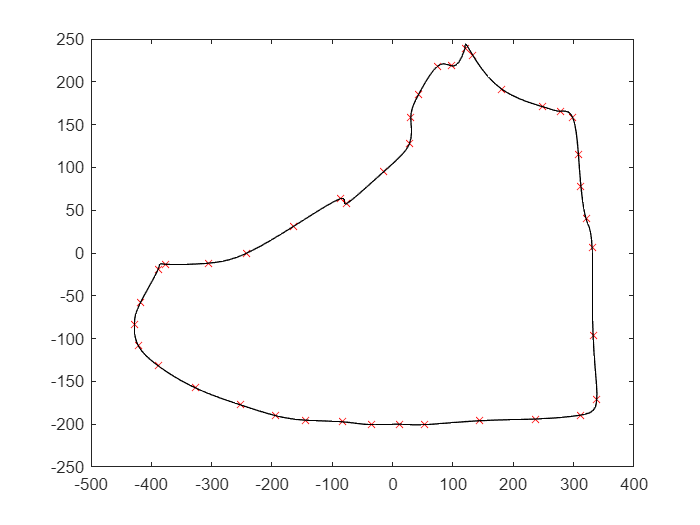

%reo una spline su una veriabile parametrica uguale al tempo
temp_scarpa = 1 : length(scarpaX);
griglia_tempo = linspace(temp_scarpa(1), temp_scarpa(end), 200);

%centro le coordinate
scarpaX_c = mean(scarpaX);
scarpaY_c = mean(scarpaY);
scarpaX = scarpaX - scarpaX_c;
scarpaY = scarpaY_c - scarpaY;

%spline sulle coordinate della nostra figura
scarpaX_s = spline(temp_scarpa, scarpaX, griglia_tempo);
scarpaY_s = spline(temp_scarpa, scarpaY, griglia_tempo);

figure(10)
plot(scarpaX, scarpaY, 'rx', scarpaX_s, scarpaY_s, '-k')

**PUNTO 2.4:**

**Calcolare il perimetro del poligono ottenuto al punto precedente tramite un'opportuna function che sarà allegata in fondo al file **`.mlx`

Il perimetro è ottenuto tramite la function scritta in fondo al file.

P_tot = perimetro(scarpaX,scarpaY)

P_tot =      2.032404394967998e+03


**PUNTO 2.5:**

**Ricostruire inoltre la curva parametrica passante per i punti definiti al punto (2.3) mediante le cubiche di Hermite (non spline cubiche). Calcolare la norma infinito del vettore contenente le ordinate assunte dalla valutazione della cubica di Hermite.**

In matlab per costruire una cubica di Hermite interpolante a tratti si usa il comando pchip che prende in input le ascisse e le ordinate dei dati da interpolare oltre che la griglia di valutazione della spline.

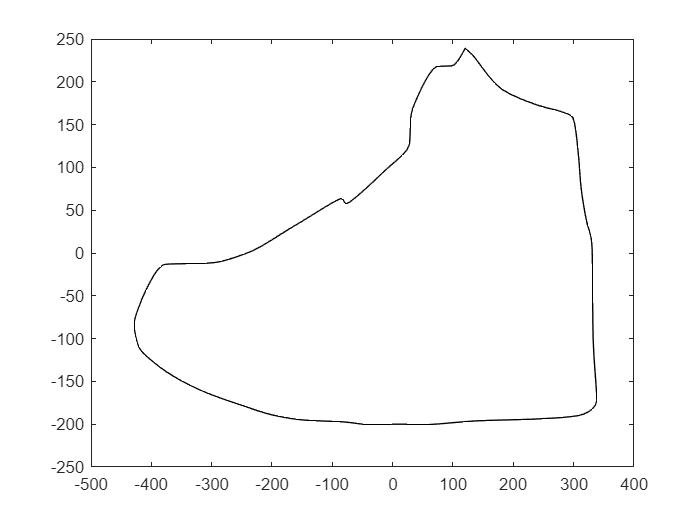

yyc = pchip(temp_scarpa,scarpaY, griglia_tempo);
xxc = pchip(temp_scarpa,scarpaX, griglia_tempo);

figure(11)
plot(xxc, yyc,'color', 'k')

Il grafico infatti ricostruisce correttamente l'immagine.

%calcolo della norma infinito
norm(yyc, inf)

ans =      2.391536100791472e+02


### **N.3 ****APPROSSIMAZIONE:**

Scaricare il dataset dell'andamento del covid da [https://github.com/pcm-dpc/COVID-19](https://github.com/pcm-dpc/COVID-19)

Caricare il dataset in matlab utilizzando il comando `readtable`.

Generare un insieme di punti $C=\{(t_i,y_i)\}_{i=1}^n$ le cui ascisse il tempo $t_1,t_2,\ldots,t_n$. I valori sono estratti dalla tabella precedentemente caricata. Scegliere una colonna a piacere che descrive un attributo della tabella. Scegliere inoltre $5 \leq n \leq 11$.

dataset = readtable("dpc-covid19-ita-andamento-nazionale.csv")

dataset = 838×24 table
           data             stato     ricoverati_con_sintomi    terapia_intensiva    totale_ospedalizzati    isolamento_domiciliare    totale_positivi    variazione_totale_positivi    nuovi_positivi    dimessi_guariti    deceduti    casi_da_sospetto_diagnostico    casi_da_screening    totale_casi    tamponi    casi_testati         note         ingressi_terapia_intensiva    note_test    note_casi    totale_positivi_test_molecolare    totale_positivi_test_antigenico_rapido    tamponi_test_molecolare    tamponi_test_antigenico_rapido
    ___________________<

ndata = 11;
c_t = (1 : ndata)';
c_y = zeros(ndata, 1);
for j = 1 : ndata
    c_y(j) = dataset.nuovi_positivi(j);
end

**PUNTO 3.1:**

**Costruire e valutare, su una griglia fitta di almeno 100 punti, utilizzando i metodi studiati, la retta dei minimi quadrati approssimante i dati.**

Creo una griglia fitta di 200 punti e calcolo i coefficienti mediante la formula $B^T B = B^T y$.

Grigliadata = linspace(1, ndata, 200);
dataset_B = [c_t, ones(size(c_t))];
dataset_A = SGauss((dataset_B' * dataset_B), (dataset_B' * c_y));

%retta dei minimi quadrati
%utilizziamo polyval per valutare i coefficienti presenti nel vettore
%dataset_A
retta = polyval(dataset_A, Grigliadata);


**PUNTO 3.2:**

**Mostrare graficamente sia il polinomio di primo grado approssimante che i punti approssimati ed evidenziare sul grafico gli scostamenti.**

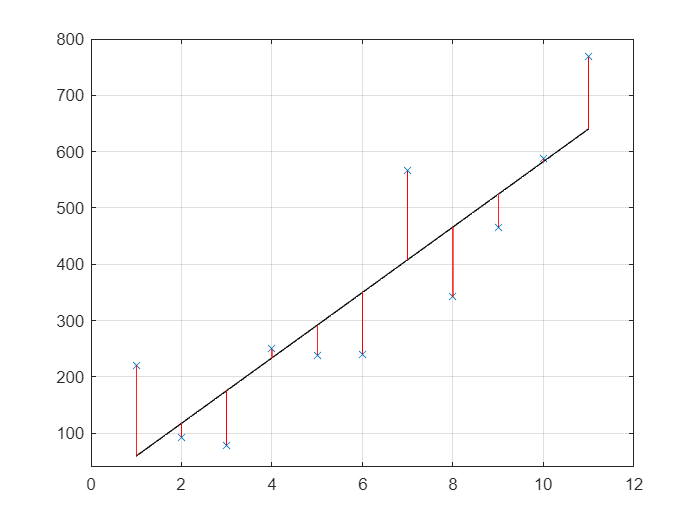

figure(12)

plot(c_t, c_y, 'x')
hold on
grid on
plot(Grigliadata,retta,'k')

%scostamenti
for i = 1 : ndata
    plot([c_t(i), c_t(i)], [polyval(dataset_A, c_t(i)), c_y(i)], 'r')
end
axis([c_t(1)-1, ndata + 1, 40, 800])
hold off

Dati i punti in figura, lo scostamento della funzione da essi è un insieme di numeri che sono le lunghezze dei segmenti indicanti la distanza tra i valori e tali punti.

**PUNTO 3.3:**

**Ripetere il punto precedente variando il grado del polinomio approssimante nell'intervallo tra 2 e 10. Mostrare tutte le curve approssimanti ottenute sullo stesso grafico.**

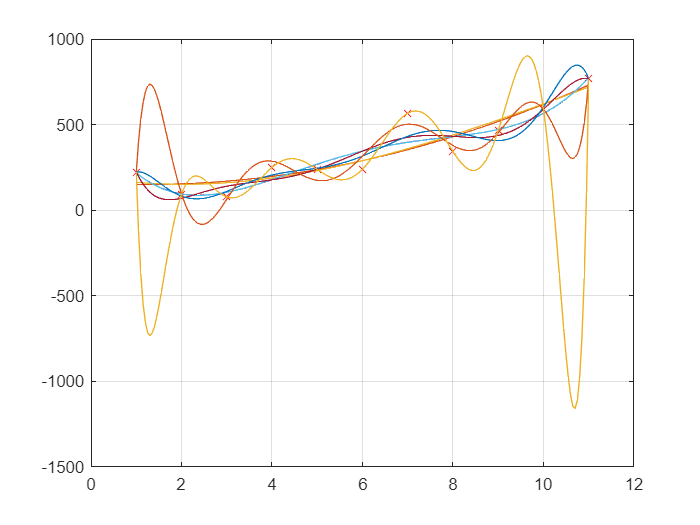

g_pol = zeros(length(Grigliadata), 9);   %da 2 a 10 è = 9

for i = 1 : 9
    g_pol(:, i) = (polyval(polyfit(c_t, c_y, i + 1), Grigliadata))';
end

figure(200)

plot(c_t, c_y, 'rx', Grigliadata, g_pol)
hold on
grid on 

Polinomi approssimati tra 2 e 10.

**PUNTO 3.4:**

**Valutare il residuo in norma due per ognuna delle curve precedentemente ottenute**

residui= zeros(ndata, 9);
for i=1:9
    %residui
    residui(:,i) = norm(abs(polyval(polyfit(c_t, c_y, i + 1), c_t) - c_y)', 2)
end

residui = 1.0e+02 *

   2.833721531064356                   0                   0                   0                   0                   0                   0                   0                   0
   2.833721531064356                   0                   0                   0                   0                   0                   0                   0                   0
   2.833721531064356                   0                   0                   0                   0                   0                   0                   0                   0
   2.833721531064356                   0                   0                   0                   0                   0                   0                   0                   0
   2.833721531064356                   0                   0                   0                   0                   0                   0                   0                   0
   2.833721531064356                   0                   0              

residui = 1.0e+02 *

   2.833721531064356   2.820835813250159                   0                   0                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159                   0                   0                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159                   0                   0                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159                   0                   0                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159                   0                   0                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159                   0              

residui = 1.0e+02 *

   2.833721531064356   2.820835813250159   2.341608137867793                   0                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793                   0                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793                   0                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793                   0                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793                   0                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793              

residui = 1.0e+02 *

   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482                   0                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823

residui = 1.0e+02 *

   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133                   0                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823

residui = 1.0e+02 *

   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672                   0                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823

residui = 1.0e+02 *

   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357                   0                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823

residui = 1.0e+02 *

   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357   1.302600354199716                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357   1.302600354199716                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357   1.302600354199716                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357   1.302600354199716                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357   1.302600354199716                   0
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823

residui = 1.0e+02 *

   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357   1.302600354199716   0.000000016078693
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357   1.302600354199716   0.000000016078693
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357   1.302600354199716   0.000000016078693
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357   1.302600354199716   0.000000016078693
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823665482   2.341496065678133   2.220235283502672   2.115067863643357   1.302600354199716   0.000000016078693
   2.833721531064356   2.820835813250159   2.341608137867793   2.341500823

### **N.4 ****QUADRATURA:**

**PUNTO 4.1:**

**Definire un dominio **$[a,b]$** ed una funzione composta **$f(x)$** in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc etc). La funzione deve essere definita, positiva e continua in **$[a,b]$**. Usare la funzione **`ezplot`** per stabilire l'intervallo **$[a,b]$**; **

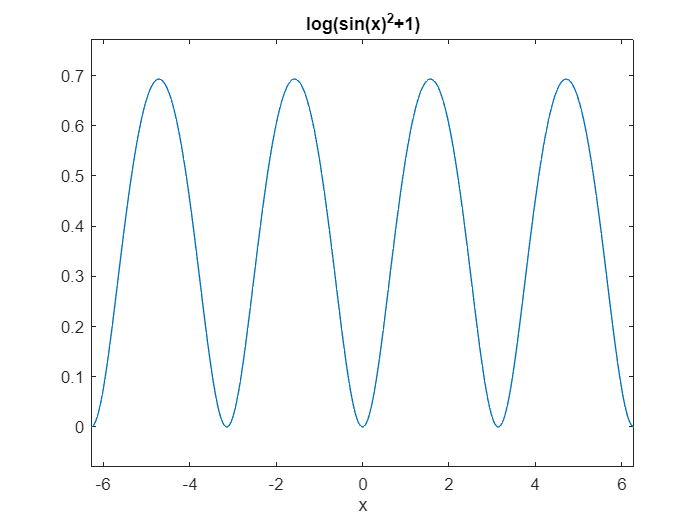

figure(25)
f2 = @(x) log(sin(x).^2 + 1);
% dichiaro ezplot per cercar un intervallo che non presenti discontinuità
ezplot(f2) 

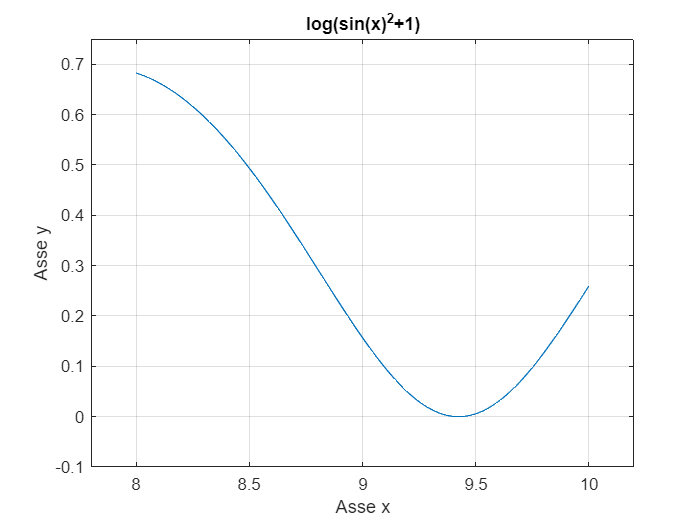

figure(22)
%scelgo dunque un intervallo tra 8 e 10

a1 = 8;
b1 = 10;

%Utilizzo ezplot per visualizzare il grafico della funzione
ezplot(f2,[a1,b1])

hold on
grid on
axis([a1 - 0.2, b1 + 0.2, -0.1, 0.75])

xlabel('Asse x')
ylabel('Asse y')

**PUNTO 4.2:**

**Considerare come valore esatto dell'integrale **$I=I[f]=\int_a^b f(x)dx$** il valore ottenuto mediante la funzione MATLAB **`integral`** con tolleranza **$10^{-9}$**;**

Integrale = integral(f2,a1,b1,'AbsTol',1e-9)

Integrale =    0.545287991153002


**PUNTO 4.3:**

**Stimare l'integrale **$I$** utilizzando le principali formule di quadratura (Rect. sx, Rect. dx, Punto medio, Trapez., Simpson) su **$1, 2,$** e **$3$** nodi e calcolare per ognuna di esse il corrispondente errore di discretizzazione. **

Formule su 1 nodo

Rect_sx = (b1-a1) * f2(a1)

Rect_sx =    1.365011259301764


errRect_sx = abs(Rect_sx - Integrale)       %errore di discretizzazione

errRect_sx =    0.819723268148762


Rect_dx = (b1-a1) * f2(b1)

Rect_dx =    0.518501875557354


errRect_dx = abs(Rect_dx - Integrale)       %errore di discretizzazione

errRect_dx =    0.026786115595648


p_med = (a1+b1)/2;                            %Calcolo del punto medio dell'intervallo
Punto_med = (b1-a1) * f2(p_med)               %quadratura del punto medio

Punto_med =    0.313736788492392


err_Pmed = abs(Punto_med - Integrale)         %errore di discretizzazione

err_Pmed =    0.231551202660610


Formula su 2 nodi

Trap = (b1-a1)/2 * (f2(a1) + f2(b1))

Trap =    0.941756567429559


err_Trap = abs(Trap- Integrale)                %errore di discretizzazione

err_Trap =    0.396468576276557


Formula su 3 nodi

Simpson = (b1-a1)/6 * (f2(a1) + 4*f2(p_med) + f2(b1))

Simpson =    0.523076714804781


err_Simp = abs(Simpson - Integrale)            %errore di discretizzazione

err_Simp =    0.022211276348221


Come ci aspettavamo infatti l'errore di Simpson è più piccolo degli errori calcolati precedentemente essendo esso un metodo molto più accurato.

**PUNTO 4.4:**

**Costruzione di formule di quadratura. Fissare **$p$ $3 \leq p \leq 5$** nodi distinti, non equispaziati, **$x_i \in [0,4]$**  di una formula di quadratura **

                                                                                   
$$Q[f]=w_1f(x_1)+w_2f(x_2)+\cdots+w_pf(x_p)$$
                            

**per il calcolo numerico dell'integrale definito della funzione **$f$** in **$[0,4]$**;**

%scelgo p nodi = 5
p = 5;
xi = [1.5 2 2.7 3 3.6];
a2 = 1.5;
b2 = 3.6;

for i = 1:p
    I(i,1) = (b2^i - a2^i)/i;
end


**PUNTO 4.5:**

**Determinare i valori dei pesi **$w_i$** affinché la formula risulti esatta per polinomi algebrici di grado al più **$p-1$** (costruire e risolvere il sistema **$B^Tw=I$**.)**

Vett = [xi.^0; xi.^1; xi.^2; xi.^3; xi.^4];
wi = SGauss(Vett,I)

wi =    0.141050000000001
   0.793800000000002
   0.183749999999979
   0.788900000000021
   0.192499999999996


## FUNCTION PERIMETRO

%function perim = perimetro(x,y)
%La seguenete function permette di calcolare il perimetro date le
%coordinate dei punti di cui calcolare il perimetro

%m = size(x, 1);         %il numero dei punto di cui calcolare il perimetro
%perim = sqrt(abs(x(1) - x(2)).^2 + abs(y(1) - y(2)).^2);
%for i = 2 : m - 1
   % perim = perim + sqrt(abs(x(i) - x(i+1)).^2 + abs(y(i) - y(i+1)).^2); 
%end
%perim = perim + sqrt(abs(x(m) - x(1)).^ 2 + abs(y(m) - y(1)).^2);
%end